# Figure 1: Superfine Contour

clear
CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData/Figure1/'])


load('Figure1_Data_S_EE=0.024_S_II=0.12_S_Elgn=0.048_7D_HPC_S_IlgnInd2_rI_L6Ind2.mat','ContourData_7D')

S_EEtest = [0.018 0.021 0.024 0.027 0.030]; 
S_IItest = [0.08  0.12  0.16  0.20];
S_EEInd = 3;
S_IIInd = 2;
S_ElgnInd = 2;
S_IlgnInd = 2;
rI_L6Ind = 2;

S_EE = S_EEtest(S_EEInd);
S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
S_Elgn=S_Elgntest(S_ElgnInd);

S_II = S_IItest(S_IIInd);
S_Ilgntest = [1.5 2 2.5 3] *S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);

## Fine Contours

CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,:)); CurrentBlowup(1:35,1:283) = 1; CurrentBlowup = logical(CurrentBlowup);
Currentsteady = squeeze(ContourData_7D.ConvIndi(:,:)); Currentsteady(1:35,1:283) = true;

CurrentBlowupModi = false(size(CurrentBlowup));
CurrentsteadyModi =  true(size(CurrentBlowup));
% first modify Blowup map
for ColInd = 1:size(CurrentBlowup,2)
    BUInds = find(CurrentBlowup(:,ColInd));
    USInds = find(~Currentsteady(:,ColInd));
    
    if length(BUInds)>=2
        CurrentBlowupModi(1:BUInds(end-1),ColInd) = true;
    end
    if length(USInds)>=1
        CurrentsteadyModi(USInds(1):USInds(end),ColInd) = false;
    end
end

% figure('Name','BlowStea')
% subplot 121
% imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,CurrentBlowupModi)
% set(gca,'YDir','Normal')
% subplot 122
% imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,CurrentsteadyModi)
% set(gca,'YDir','Normal')

% Merge the blowup and unsteady map
% Blowup place is 1 black


BlowSteadShow = double(CurrentBlowupModi)+0.5*double(~CurrentsteadyModi);
BlowSteadShow(BlowSteadShow>1) = 0.5;
for ColInd = 1:size(BlowSteadShow,2)
    
    BUInds = find(BlowSteadShow(:,ColInd) == 1);
    USInds = find(BlowSteadShow(:,ColInd) == 0.5);
    
    if isempty(USInds)
        continue
    end
    BUInds(BUInds<=max(USInds)) = [];
    
    if isempty(BUInds)
        continue
    end
    
    BlowSteadShow(BUInds(1):BUInds(end),ColInd) = 0.5;
end
BlowSteadShow(BlowSteadShow == 1) = 0.5;

Fig1 = figure('Name','Figure1','units','normalized','outerposition',[0 0 1 0.7]);
%convolution mat
KerSize = 6;
ConvMat = 1/KerSize^2*ones(KerSize);
%cmap = [1,1,1; 0.5, 0.5, 0.5; 0, 0, 0];
BlowSteadimage = cat(3,1-BlowSteadShow,1-BlowSteadShow,1-BlowSteadShow);


### The first panel

ax0 = subplot(121);
hold all
image(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,BlowSteadimage)
set(gca,'YDir','Normal')
%colormap(cmap);


E contours

CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: ));
CurrentFrE = FrRateModify(CurrentFrE, 1,CurrentBlowupModi,CurrentsteadyModi);
[C1r,h1r]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrE,[1:8 ],'ShowText','off','color',1-[0,1,1]*0.25);

CurrentFrESm = FrRateModify(CurrentFrE, ConvMat,CurrentBlowupModi,CurrentsteadyModi);
[C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrESm,[1:8 ],'ShowText','off','color','r');
h1.LineWidth = 0.1;

%h1k.LineWidth = 0.1;
%clabel(C1,h1,'FontSize',8,'Color','k')
%clabel(C1,h1,'FontSize',12,'Color',[0.5 0 0],'labelspacing',3700)


I contours

CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
CurrentFrI = FrRateModify(CurrentFrI, 1,CurrentBlowupModi,CurrentsteadyModi);
[C2r,h2r]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrI,[6:3:27],'ShowText','off','color',1-[1,1,0]*0.25);

CurrentFrISm = FrRateModify(CurrentFrI, ConvMat,CurrentBlowupModi,CurrentsteadyModi);
[C2,h2]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrISm,[6:3:27],'ShowText','off','color','b');
h2.LineWidth = 0.1; 


Good area contours

CurrentFrEGA = CurrentFrESm; CurrentFrIGA = CurrentFrISm;
CurrentFrEGA(~(CurrentFrESm>=2.85 & CurrentFrESm<=5.5 & ...
           CurrentFrISm./CurrentFrESm    >=2.85 & ...
           CurrentFrISm./CurrentFrESm    <=4.35)) = nan;
CurrentFrIGA(~(CurrentFrESm>=2.85 & CurrentFrESm<=5.5 & ...
           CurrentFrISm./CurrentFrESm    >=2.85 & ...
           CurrentFrISm./CurrentFrESm    <=4.35)) = nan;       

[C1k,h1k]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrEGA,[3 5 ],'ShowText','off','color','k','linestyle','--');
h1k.LineWidth = 3;  
[C2k,h2k]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrIGA./CurrentFrEGA,[3 4.25 ],'ShowText','off','color','k','linestyle','--');
h2k.LineWidth = 3;  


clabel and label

%clabel(C2,h2,'FontSize',8,'Color','k')
%clabel(C2,h2,'FontSize',12,'Color',[0 0 0.5],'labelspacing',3700)
clabel(C1,'manual','FontSize',12,'Color',[0.5 0 0])

 
    Please wait a moment...
 
   Carefully select contours for labeling.
   When done, press RETURN while the Graph window is the active window.


clabel(C2,'manual','FontSize',12,'Color',[0 0 0.5])

 
    Please wait a moment...
 
   Carefully select contours for labeling.
   When done, press RETURN while the Graph window is the active window.



SIE_SII = 0.147; SEI_SEE = 1.51;
scatter(SIE_SII, SEI_SEE, 200, 'p')
hold off
xlabel('S^{IE}/S^{II}');ylabel('S^{EI}/S^{EE}')

axis square
axis([0.1 0.22 1 2.2])

### The second panel

GreyHem = ones(size(CurrentFrE));
GreyHemAlpha = BlowSteadShow; 

%FrE. plot first data 
ax1a = subplot(2,2,2); 
originalSize = get(ax1a, 'Position');
CurrentFrEShow = CurrentFrE;
CurrentFrEShow(CurrentFrE>=3 & CurrentFrE<=5 & ...
               CurrentFrI./CurrentFrE    >=3 & ...
               CurrentFrI./CurrentFrE    <=4.25) = -1;
im1a = imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrEShow)

im1a =   Image with properties:

           CData: [320×320 double]
    CDataMapping: 'scaled'

  Show all properties


set(ax1a,'YDir','normal')
axis square; 
axis([0.1 0.22 1 2.2])
hold all; 
[C1s,h1s]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                     CurrentFrEGA,[3 5],'ShowText','off','color','k','linestyle','--');
h1s.LineWidth = 1;  
[C2s,h2s]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                     CurrentFrIGA./CurrentFrEGA,[3 4.25],'ShowText','off','color','k','linestyle','--');
h2s.LineWidth = 1; 
cb1 = colorbar(ax1a);
set(ax1a,'Position',originalSize)
title('f_E')
xlabel('S^{IE}/S^{II}');ylabel('S^{EI}/S^{EE}')
%plot second data 
ax1b = axes('Position',originalSize); 
im1b = imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,GreyHem); 
im1b.AlphaData = GreyHemAlpha; % change this value to change the foreground image transparency 
axis square; 
axis([0.1 0.22 1 2.2])
%link axes 
linkaxes([ax1a,ax1b]) 
%%Hide the top axes 
ax1b.Visible = 'off'; 
ax1b.XTick = []; 
ax1b.YTick = []; 
set(ax1b,'YDir','normal')
%add differenct colormap to different data if you wish 
cmap = [1,1,1; jet];
colormap(ax1a,cmap) 
colormap(ax1b,[0,0,0]) 
%set the axes and colorbar position 
%set([ax1,ax2],'Position',[.17 .11 .685 .815]); 
%cb2 = colorbar(ax2,'Position',[.88 .11 .0675 .815]); 


%FrI. plot first data 
ax2a = subplot(2,2,4); 
originalSize = get(ax2a, 'Position');
CurrentFrIShow = CurrentFrI;
CurrentFrIShow(CurrentFrE>=3 & CurrentFrE<=5 & ...
               CurrentFrI./CurrentFrE    >=3 & ...
               CurrentFrI./CurrentFrE    <=4.25) = -1;
im1a = imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrIShow)

im1a =   Image with properties:

           CData: [320×320 double]
    CDataMapping: 'scaled'

  Show all properties


set(ax2a,'YDir','normal')
axis square; 
axis([0.1 0.22 1 2.2])
hold all; 
[C3s,h3s]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                     CurrentFrEGA,[3 5],'ShowText','off','color','k','linestyle','--');
h3s.LineWidth = 1;  
[C4s,h4s]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                     CurrentFrIGA./CurrentFrEGA,[3 4.25],'ShowText','off','color','k','linestyle','--');
h4s.LineWidth = 1; 
cb2 = colorbar(ax2a);
set(ax2a,'Position',originalSize)
title('f_I')
xlabel('S^{IE}/S^{II}');ylabel('S^{EI}/S^{EE}')
%plot second data 
ax2b = axes('Position',originalSize); 
im1b = imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,GreyHem); 
im1b.AlphaData = GreyHemAlpha; % change this value to change the foreground image transparency 
axis square; 
axis([0.1 0.22 1 2.2])
%link axes 
linkaxes([ax2a,ax2b]) 
%%Hide the top axes 
ax2b.Visible = 'off'; 
ax2b.XTick = []; 
ax2b.YTick = []; 
set(ax2b,'YDir','normal')
%add differenct colormap to different data if you wish 
cmap = [1,1,1; jet];
colormap(ax2a,cmap) 
colormap(ax2b,[0,0,0]) 


Save figures

Paperpath = [CurrentFolder '\Figure for Paper\'];
FigName1 = 'Figure1';
savefig(Fig1,[Paperpath FigName1 '.fig']);

Print Figs

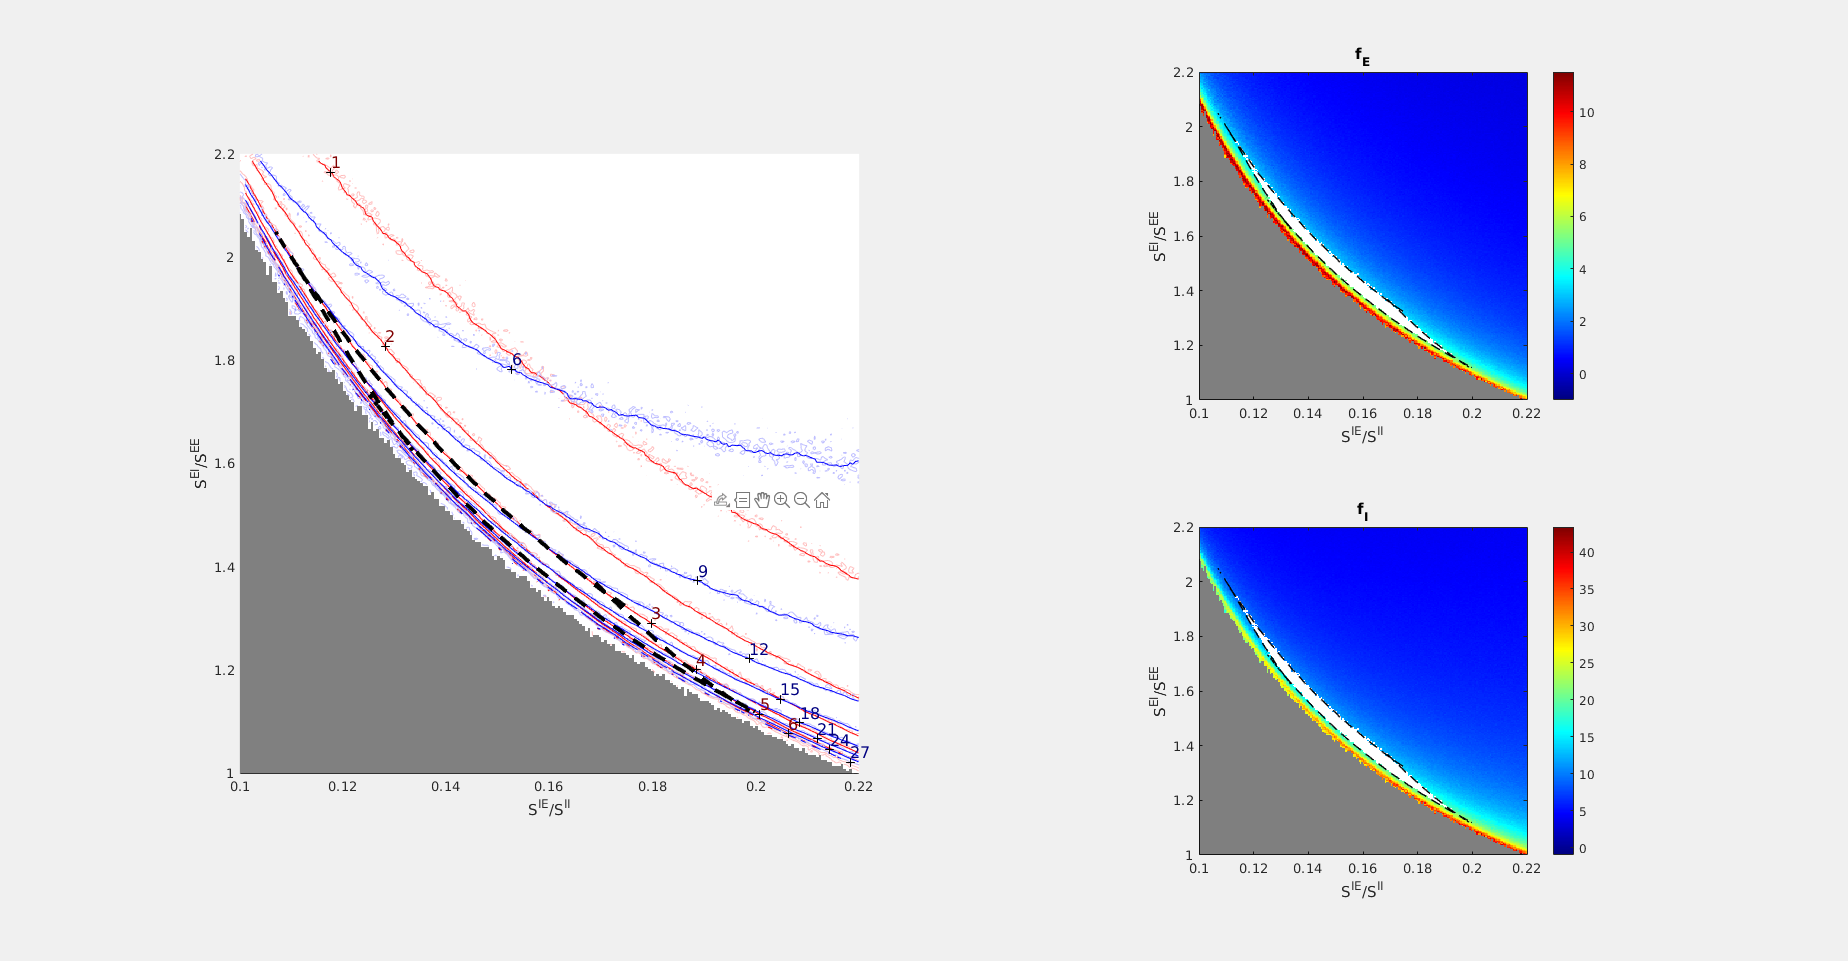

Fig1.PaperUnits = 'centimeters';
Fig1.PaperSize = [42,15];
Fig1.PaperOrientation = "landscape";
exportgraphics(Fig1,[Paperpath FigName1 '.pdf'],'Resolution',600)

## SI: FrE and FrI/E contours

CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,:)); CurrentBlowup(1:35,1:283) = 1; CurrentBlowup = logical(CurrentBlowup);
Currentsteady = squeeze(ContourData_7D.ConvIndi(:,:)); Currentsteady(1:35,1:283) = true;

CurrentBlowupModi = false(size(CurrentBlowup));
CurrentsteadyModi =  true(size(CurrentBlowup));
% first modify Blowup map
for ColInd = 1:size(CurrentBlowup,2)
    BUInds = find(CurrentBlowup(:,ColInd));
    USInds = find(~Currentsteady(:,ColInd));
    
    CurrentBlowupModi(1:BUInds(end-1),ColInd) = true;
    CurrentsteadyModi(USInds(1):USInds(end),ColInd) = false;
end

% figure('Name','BlowStea')
% subplot 121
% imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,CurrentBlowupModi)
% set(gca,'YDir','Normal')
% subplot 122
% imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,CurrentsteadyModi)
% set(gca,'YDir','Normal')

% Merge the blowup and unsteady map
% Blowup place is 1 black


BlowSteadShow = double(CurrentBlowupModi)+0.5*double(~CurrentsteadyModi);
BlowSteadShow(BlowSteadShow>1) = 0.5;
for ColInd = 1:size(BlowSteadShow,2)
    
    BUInds = find(BlowSteadShow(:,ColInd) == 1);
    USInds = find(BlowSteadShow(:,ColInd) == 0.5);
    
    if isempty(USInds)
        continue
    end
    BUInds(BUInds<=max(USInds)) = [];
    
    if isempty(BUInds)
        continue
    end
    
    BlowSteadShow(BUInds(1):BUInds(end),ColInd) = 0.5;
end
BlowSteadShow(BlowSteadShow == 1) = 0.5;

FigS1 = figure('Name','FigureS1','units','normalized','outerposition',[0 0 0.6 1]);
%convolution mat
KerSize = 8;
ConvMat = 1/KerSize^2*ones(KerSize);
%cmap = [1,1,1; 0.5, 0.5, 0.5; 0, 0, 0];
BlowSteadimage = cat(3,1-BlowSteadShow,1-BlowSteadShow,1-BlowSteadShow);


hold all
image(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,BlowSteadimage)
set(gca,'YDir','Normal')
%colormap(cmap);


E contours

CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: ));
CurrentFrE = FrRateModify(CurrentFrE, 1,CurrentBlowupModi,CurrentsteadyModi);
[CS1r,hS1r]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrE,[1:8 ],'ShowText','off','color',1-[0,1,1]*0.25);

CurrentFrESm = FrRateModify(CurrentFrE, ConvMat,CurrentBlowupModi,CurrentsteadyModi);
[CS1,hS1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrESm,[1:8 ],'ShowText','off','color','r');
hS1.LineWidth = 0.1;

%h1k.LineWidth = 0.1;
%clabel(C1,h1,'FontSize',8,'Color','k')
%clabel(C1,h1,'FontSize',12,'Color',[0.5 0 0],'labelspacing',3700)


I contours

CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
CurrentFrI = FrRateModify(CurrentFrI, 1,CurrentBlowupModi,CurrentsteadyModi);
[CS2r,hS2r]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                     CurrentFrI./CurrentFrE,[2:.5:7],'ShowText','off','color',1-[1,0,1]*0.25);

CurrentFrISm = FrRateModify(CurrentFrI, ConvMat,CurrentBlowupModi,CurrentsteadyModi);
[CS2,hS2]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                   CurrentFrISm./CurrentFrESm,[2:.5:7],'ShowText','off','color','g');
hS2.LineWidth = 0.1; 


Good area contours

CurrentFrEGA = CurrentFrESm; CurrentFrIGA = CurrentFrISm;
CurrentFrEGA(~(CurrentFrESm>=2.9 & CurrentFrESm<=5.5 & ...
           CurrentFrISm./CurrentFrESm    >=2.9 & ...
           CurrentFrISm./CurrentFrESm    <=4.35)) = nan;
CurrentFrIGA(~(CurrentFrESm>=2.9 & CurrentFrESm<=5.5 & ...
           CurrentFrISm./CurrentFrESm    >=2.9 & ...
           CurrentFrISm./CurrentFrESm    <=4.35)) = nan;       

[C1k,h1k]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrEGA,[3 5 ],'ShowText','off','color','k','linestyle','--');
h1k.LineWidth = 3;  
[C2k,h2k]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrIGA./CurrentFrEGA,[3 4.25 ],'ShowText','off','color','k','linestyle','--');
h2k.LineWidth = 3;  


clabel and label

%clabel(C2,h2,'FontSize',8,'Color','k')
%clabel(C2,h2,'FontSize',12,'Color',[0 0 0.5],'labelspacing',3700)
clabel(CS1,'manual','FontSize',12,'Color',[0.5 0 0])

 
    请稍候...
 
   仔细选择要用于标记的等高线。
   完成后，当图形窗口为活动窗口时，请按 Return 键。


clabel(CS2,'manual','FontSize',12,'Color',[0 0 0.5])

 
    请稍候...
 
   仔细选择要用于标记的等高线。
   完成后，当图形窗口为活动窗口时，请按 Return 键。


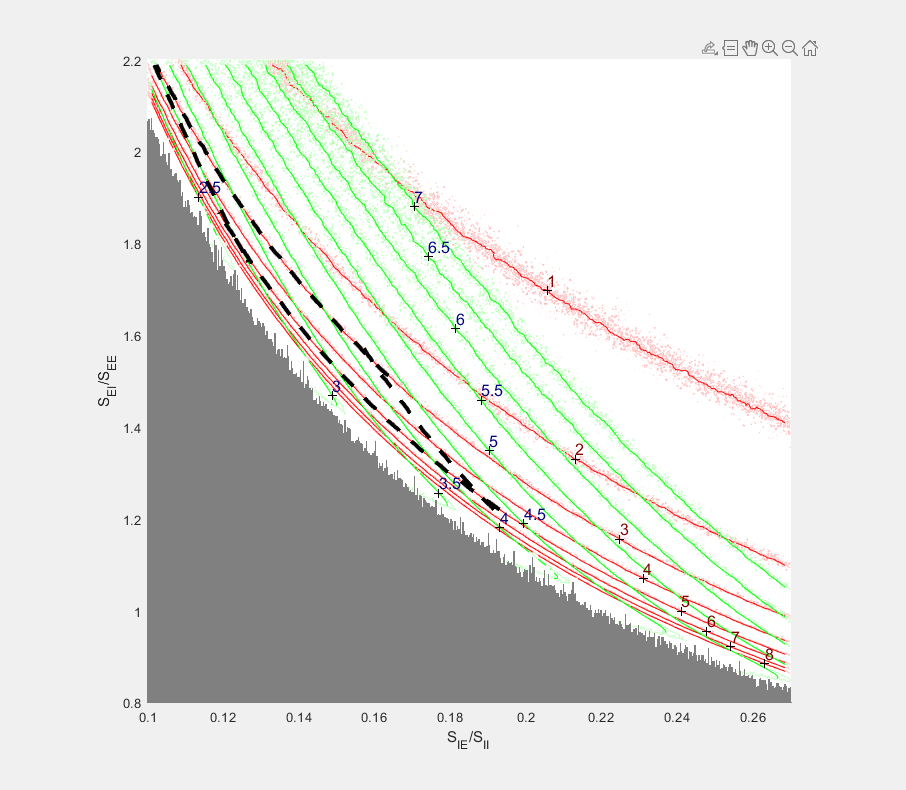


xlabel('S_{IE}/S_{II}');ylabel('S_{EI}/S_{EE}')
hold off
axis square


% title(sprintf('S_{EE}=%.3f; S_{II}=%.3f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
%                S_EE,        S_II,        S_Elgn,        S_Ilgn))
